# INTERPOLACJA

## Interpolacja trygonometryczna i jej właściwości

**UWAGA!** W tych ćwiczeniach, poza ćwiczeniem 1, celowo nie podawany jest pełen kod budujący układy równań interpolacyjne takie jak omawiane w części 1 zajęć ze względu na fakt, że typowe implementacje opierają się o bardziej zaawansowane wbudowane funkcje, które poznamy pod koniec tego modułu. Metoda podręcznikowa używana w punkcie 1 ma złe właściwości numeryczne związane z uwarunkowaniem macierzy układu równań.

**ĆWICZENIE 1:**

W tym ćwiczeniu będziemy się starali odwzorować różne funkcje okresowe za pomocą bazy funkcji podstawowej interpolacji trygonometrycznej:


$$\begin{array}{l}
a_0 =1\\
a_1 =\sin \left(x\right)\\
b_1 =\cos \left(x\right)\\
a_2 =\sin \left(2x\right)\\
b_2 =\cos \left(2x\right)\\
\ldotp \ldotp \ldotp 
\end{array}$$


Zwróć uwagę, ze w świetle szeregu Taylora ta baza ma stały i wbudowany okres 2π. Nadaje się więc wyłącznie do odtwarzania i analizy funkcji których okres podstawowy jest równy 2π.

a) dokonaj interpolacji trygonometrycznej prostej funkcji sin() lub cos() i przyjrzyj się współczynnikom obliczonym w wyniku obliczeń. Wypróbuj różne ilości punktów i okresy np. funkcję sin(11x) i 10 punktów. Zaobserwuj jak to wpływa na obliczone współczynniki. Czy widzisz analogie z przykładem dotyczącym wielomianów?

b) wykonaj kod dla funkcji innej niż trygonometryczna np. funkcji prostokątnej lub piłokształtnej (są to typowe przebiegi wykorzystywane w sprzęcie elektronicznym). Zobacz czy teraz potrafisz zinterpretować otrzymane współczynniki. Czy widzisz jakieś zależności?

%Funkcja oryginalna
f=@(x) sin(4*x);                      %przykład prostej funkcji trygonometrycznej
% f=@(x) square(x);                      %przykład funkcji prostokątnej o okresie 2pi
%f=@(x) pi*(-sawtooth(x,0.5)-1)/2;      %przykład funkcji piłokształtnej o okresie 2pi

noOfPoints = 11;

%% DALEJ NIE WPROWADZAJ ZMIAN
%Położenia węzłów
xw = linspace(-pi, pi, noOfPoints);
yw = f(xw);

% Wykonanie interpolacji trygonometrycznej i wypisanie współczynników
[a,b,yfit] = Fseries(xw,yw,(numel(xw)-1)/2);
for i=1:1:numel(a)
    fprintf('Współczynnik a%d = %0.2e\n',i,a(i));
end

Współczynnik a1 = 0.00e+00
Współczynnik a2 = 2.94e-32
Współczynnik a3 = -1.73e-32
Współczynnik a4 = 1.10e-32
Współczynnik a5 = -2.55e-32
Współczynnik a6 = 0.00e+00
Współczynnik a7 = 0.00e+00
Współczynnik a8 = 0.00e+00
Współczynnik a9 = 2.23e-32
Współczynnik a10 = 0.00e+00


for i=1:1:numel(b)
    fprintf('Współczynnik b%d = %0.2e\n',i,b(i));
end

Współczynnik b1 = 0.00e+00
Współczynnik b2 = -1.22e-16
Współczynnik b3 = 0.00e+00
Współczynnik b4 = 0.00e+00
Współczynnik b5 = -2.96e-16
Współczynnik b6 = 0.00e+00
Współczynnik b7 = 0.00e+00
Współczynnik b8 = 0.00e+00
Współczynnik b9 = 5.07e-17


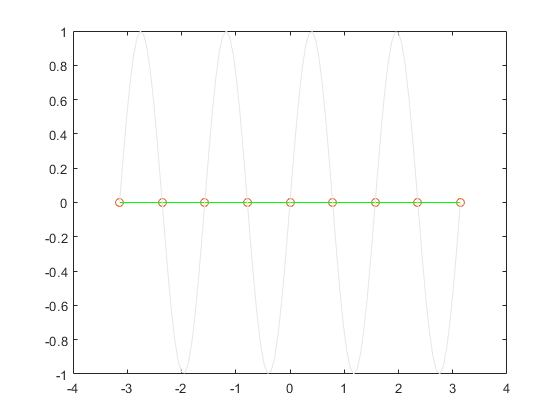


%Rysunki
xfine = linspace(min(xw),max(xw))';
yfine = Fseriesval(a,b,xfine); 

plot(xw,yw,'ko',xw,yfit,'o',xfine,yfine,'g-'); hold on;
plot(xfine, f(xfine),'Color',[0.9 0.9 0.9]); hold off;

**ĆWICZENIE 2:**

Wykonaj poniższy kod - zwróć uwagę jak zachowuje się interpolacja trygonometryczna - a konkretniej jej dokładność w sensie odwzorowania kształtu pomiędzy węzłami w miarę dodawania kolejnych funkcji z bazy (zwiększania ilości węzłów). 

Zaobserwuj, że w odróżnieniu od bazy wielomianowej nie występuje tutaj efekt Rungego (co jest spowodowane innymi właściwościami funkcji trygonometrycznych niż wielomianów) i dodawanie kolejnych punktów co do zasady zwiększa dokładność interpolacji (ograniczeniem są wyłącznie efekty numeryczne).

Sprawdź te właściwości dla różnych funkcji okresowych.

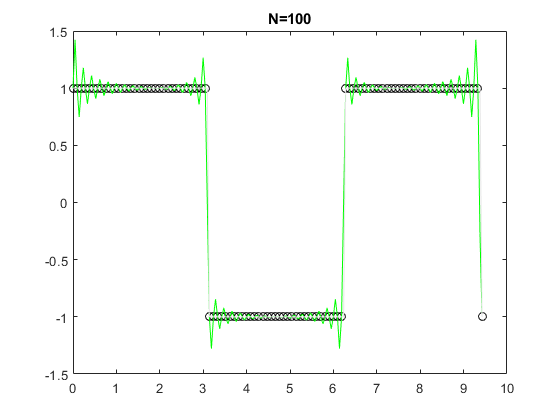

%Funkcja oryginalna
%f=@(x) sin(11*x);                      %przykład prostej funkcji trygonometrycznej
f=@(x) square(x);                      %przykład funkcji prostokątnej o okresie 2pi
%f=@(x) pi*(-sawtooth(x,0.5)-1)/2;      %przykład funkcji piłokształtnej o okresie 2pi

N=200;

%% DALEJ NIE WPROWADZAJ ZMIAN
for k=10:2:100
%Położenia węzłów
xw = linspace(0, 3*pi, k);

dx = (max(xw)-min(xw))/k;
yw = f(xw);
dx=diff(xw);
dx=dx(1);

% Wykonanie interpolacji trygonometrycznej i wypisanie współczynników
yfit = interpft(yw,N);


dy = dx*length(xw)/N;
x2 = min(xw):dy:max(xw);

yfit = yfit(1:length(x2));

%Rysunki
plot(xw,yw,'ko',x2,yfit,'g-'); hold on;
plot(x2, f(x2),'Color',[0.9 0.9 0.9]); hold off;
title(['N=' num2str(k)])

pause(1)
end

**WYKROZYSTYWANE FUNKCJE**

% Poniższy kod zaczerpnięto z:
% Matt Tearle (2021). Simple real Fourier series approximation 
% (https://www.mathworks.com/matlabcentral/fileexchange/31013-simple-real-fourier-series-approximation), 
% MATLAB Central File Exchange. Retrieved August 28, 2021.
%
% Copyright (c) 2020, The MathWorks, Inc.
% All rights reserved.
% 
% Redistribution and use in source and binary forms, with or without
% modification, are permitted provided that the following conditions are met:
% 
% * Redistributions of source code must retain the above copyright notice, this
%   list of conditions and the following disclaimer.
% 
% * Redistributions in binary form must reproduce the above copyright notice,
%   this list of conditions and the following disclaimer in the documentation
%   and/or other materials provided with the distribution.
% * In all cases, the software is, and all modifications and derivatives of the
%   software shall be, licensed to you solely for use in conjunction with
%   MathWorks products and service offerings.
% 
% THIS SOFTWARE IS PROVIDED BY THE COPYRIGHT HOLDERS AND CONTRIBUTORS "AS IS"
% AND ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, BUT NOT LIMITED TO, THE
% IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE ARE
% DISCLAIMED. IN NO EVENT SHALL THE COPYRIGHT OWNER OR CONTRIBUTORS BE LIABLE
% FOR ANY DIRECT, INDIRECT, INCIDENTAL, SPECIAL, EXEMPLARY, OR CONSEQUENTIAL
% DAMAGES (INCLUDING, BUT NOT LIMITED TO, PROCUREMENT OF SUBSTITUTE GOODS OR
% SERVICES; LOSS OF USE, DATA, OR PROFITS; OR BUSINESS INTERRUPTION) HOWEVER
% CAUSED AND ON ANY THEORY OF LIABILITY, WHETHER IN CONTRACT, STRICT LIABILITY,
% OR TORT (INCLUDING NEGLIGENCE OR OTHERWISE) ARISING IN ANY WAY OUT OF THE USE
% OF THIS SOFTWARE, EVEN IF ADVISED OF THE POSSIBILITY OF SUCH DAMAGE.

function [a,b,yfit] = Fseries(x,y,n,scale,sincos)
% FSERIES Computes real Fourier series approximation to a data set
%
% [A,B] = FSERIES(X,Y,N) fits an Nth order Fourier expansion of the form
%    y = A_0/2 + Sum_k[ A_k cos(kx) + B_k sin(kx) ]
% to the data in the vectors X & Y, using a least-squares fit.
%
% [A,B,YFIT] = FSERIES(X,Y,N) also returns a vector YFIT of the y values
% obtained by evaluating the fitted model at the values in X.
%
% [A,B,YFIT] = FSERIES(X,Y,N,RESCALING) scales the X data to lie in the
% interval [-pi,pi] if RESCALING is TRUE (default).  If RESCALING is
% FALSE, no rescaling of X is performed.
%
% [A,B,YFIT] = FSERIES(X,Y,N,RESCALING,TYPE) uses a sine expansion if TYPE
% is 'sin' or a cosine expansion if TYPE is 'cos'.  Both A & B are still
% returned, however A will be all zero if TYPE = 'sin' and B will be all
% zero if TYPE = 'cos'.
%
% See also: Fseriesval

if nargin<3
    error('MATLAB:Fseries:MissingInputs','Required inputs are x, y, and n')
end
%  HACK! to deal with variable number of inputs, without using varargin,
%  which is uninformative as a function signature
switch nargin
    case 3
        [x,y,n,scale,sincos,xrow] = checkinputs(x,y,n);
    case 4
        [x,y,n,scale,sincos,xrow] = checkinputs(x,y,n,scale);
    case 5
        [x,y,n,scale,sincos,xrow] = checkinputs(x,y,n,scale,sincos);
    otherwise
        error('MATLAB:Fseries:TooManyInputs','Too many inputs')
end

% scale x to [-pi,pi]
if scale
    x1 = min(x);
    x2 = max(x);
    x = pi*(2*(x-x1)/(x2-x1) - 1);
end

% make design matrix
nx = x*(1:n);
if isequal(sincos,'b')
    F = [0.5*ones(size(x)),cos(nx),sin(nx)];
elseif isequal(sincos,'c')
    F = [0.5*ones(size(x)),cos(nx)];
else
    F = sin(nx);
end

% do fit
c = F\y;

% extract coefficients
if isequal(sincos,'b')
    a = c(1:n+1);
    b = c(n+2:end);
elseif isequal(sincos,'c')
    a = c;
    b = zeros(n,1);
else
    a = zeros(n+1,1);
    b = c;
end

% evaluate fit
yfit = F*c;

% transpose yfit back to a row, if y was a row
if xrow
    yfit = yfit';
end

end
function [x,y,n,scale,sincos,xrow] = checkinputs(x,y,n,scale,sincos)
% x & y values
if isnumeric(x) && isvector(x) && isnumeric(y) && isvector(y)
    if ~isequal(size(x),size(y))
        throwAsCaller(MException('MATLAB:Fseries:UnequalData','x and y must be same size'))
    end
    % transpose x & y to columns if they are rows
    if size(x,2)>1
        x = x';
        y = y';
        xrow = true;
    else
        xrow = false;
    end
    % remove anything not finite and real
    idx = ~(isfinite(x) & isfinite(y) & isreal(x) & isreal(y));
    x(idx) = [];
    y(idx) = [];
    if isempty(x)
        throwAsCaller(MException('MATLAB:Fseries:NoData','x and y contain no real, finite data'))
    end
else
    throwAsCaller(MException('MATLAB:Fseries:WrongDataType','x and y values must be numeric vectors'))
end
% number of terms
if isscalar(n) && isnumeric(n)
    if n<0
        throwAsCaller(MException('MATLAB:Fseries:NegativeTerms','Number of terms (n) cannot be negative!'));
    end
else
    throwAsCaller(MException('MATLAB:Fseries:WrongDataType','n must be a numeric scalar'))
end
% optional scaling argument
if exist('scale','var')
    if ~islogical(scale)
        throwAsCaller(MException('MATLAB:Fseries:WrongDataType','Scaling parameter must be logical (true/false)'))
    end
else
    scale = true;
end
% optional type argument
if exist('sincos','var')
    if ischar(sincos)
        sincos = lower(sincos);
        if ismember(sincos,{'s','sin','sine'})
            sincos = 's';
        elseif ismember(sincos,{'c','cos','cosine'})
            sincos = 'c';
        else
            throwAsCaller(MException('MATLAB:Fseries:WrongFourierType',['Unknown type: ',sincos]))
        end
    else
        throwAsCaller(MException('MATLAB:Fseries:WrongDataType','Type must be string (''sin'' or ''cos'')'))
    end
else
    sincos = 'b';
end
end

function y = Fseriesval(a,b,x,scale)
% FSERIESVAL Evaluates real Fourier series approximation at given data values
%
% Y = FSERIESVAL(A,B,X) the Fourier expansion of the form
%    y = A_0/2 + Sum_k[ A_k cos(kx) + B_k sin(kx) ]
% at the data values in the vector X.
%
% Y = FSERIESVAL(A,B,X,RESCALING) scales the X data to lie in the interval
% [-pi,pi] if RESCALING is TRUE (default).  If RESCALING is FALSE, no
% rescaling of X is performed.
%
% See also: Fseries

if nargin<3
    error('MATLAB:Fseriesval:MissingInputs','Required inputs are a, b, and x')
end
%  HACK! to deal with variable number of inputs, without using varargin,
%  which is uninformative as a function signature
switch nargin
    case 3
        [n,x,scale,xrow] = checkInputs(a,b,x);
    case 4
        [n,x,scale,xrow] = checkInputs(a,b,x,scale);
    otherwise
        error('MATLAB:Fseriesval:TooManyInputs','Too many inputs')
end

% scale x to [-pi,pi]
if scale
    x1 = min(x);
    x2 = max(x);
    x = pi*(2*(x-x1)/(x2-x1) - 1);
end

% make design matrix
nx = x*(1:n);
F = [0.5*ones(size(x)),cos(nx),sin(nx)];

% evaluate fit
y = F*[a;b];

% transpose y back to a row, if x was a row
if xrow
    y = y';
end
end

function [n,x,scale,xrow] = checkInputs(a,b,x,scale)
% coefficients
if isnumeric(a) && isvector(a) && isnumeric(b) && isvector(b)
    % get number of terms in F series
    n = length(b);
    if length(a) ~= (n+1)
        throwAsCaller(MException('MATLAB:Fseriesval:InconsistentCoeffs','Inconsistent coefficient vectors'))
    end
else
    throwAsCaller(MException('MATLAB:Fseriesval:WrongDataType','Coefficients must be numeric vectors'))
end
% x values
if isnumeric(x) && isvector(x)
    % transpose x to a column if it is a row
    if size(x,2)>1
        x = x';
        xrow = true;
    else
        xrow = false;
    end
else
    throwAsCaller(MException('MATLAB:Fseriesval:WrongDataType','x values must be a numeric vector'))
end
% optional scaling argument
if exist('scale','var')
    if ~islogical(scale)
        throwAsCaller(MException('MATLAB:Fseriesval:WrongDataType','Scaling parameter must be logical (true/false)'))
    end
else
    scale = true;
end
end
